# Least Square

## Practice 1: Estimate mass of vehicle

### Problem

There is an accelerating vehicle. This vehicle is a **two-wheel drive**, and the **diameter** of each wheel is **600** **mm**.

If we can control the torque of the wheel, use the **input torque** and **measured acceleration** to determine the **mass of the vehicle**.

The torque is the value for one wheel.

(Assume that the torque is transferred to the ground without any errors or losses.)

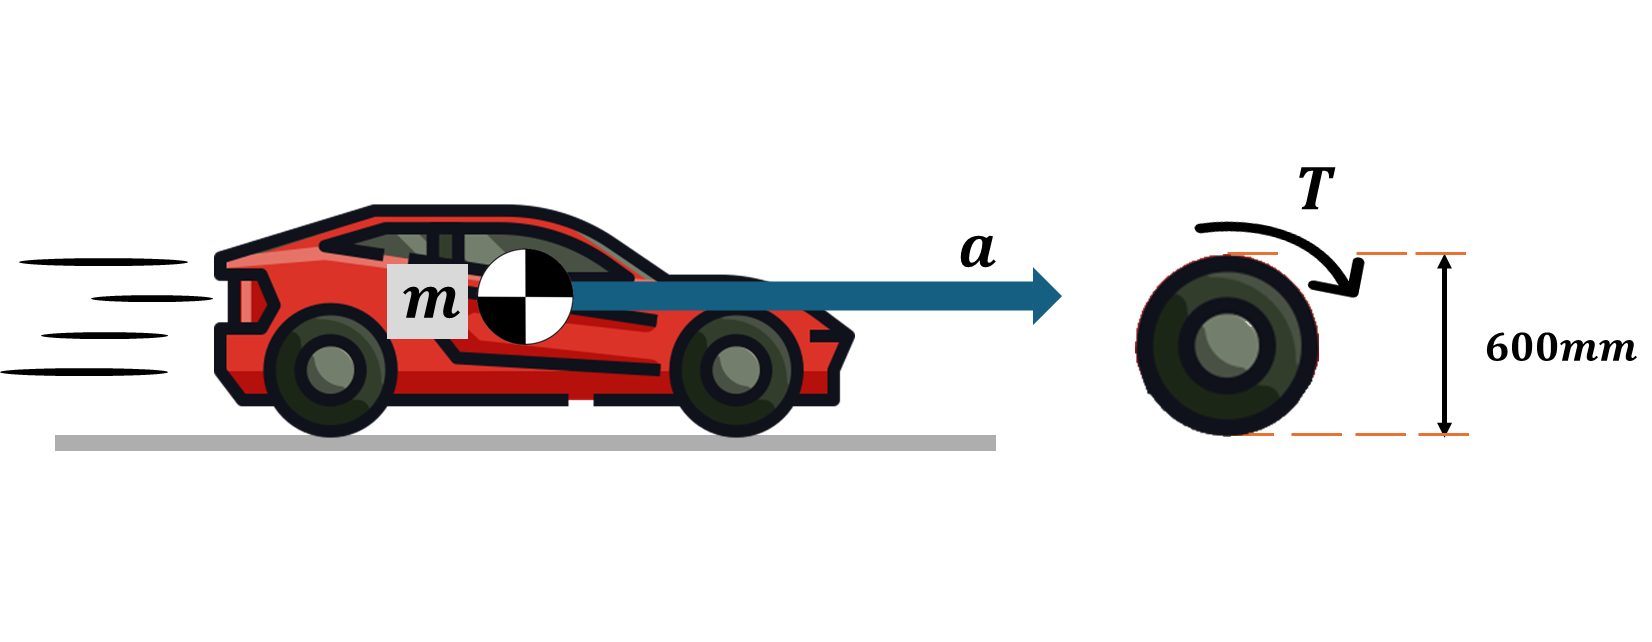

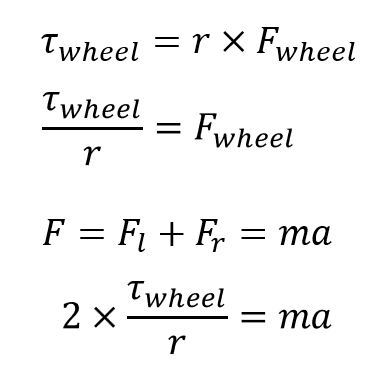

- τ_wheel : Wheel **torque**

- r : **Radius** of the wheel

- F_wheel : Wheel **force**

- F : **Total force** applied to the vehicle

- F_l : **Force** due to the **left wheel**

- F_r : **Force** due to the **right wheel**

- m : **Mass** of the vehicle

- a : **Acceleration** of the vehicle

### Measurement data

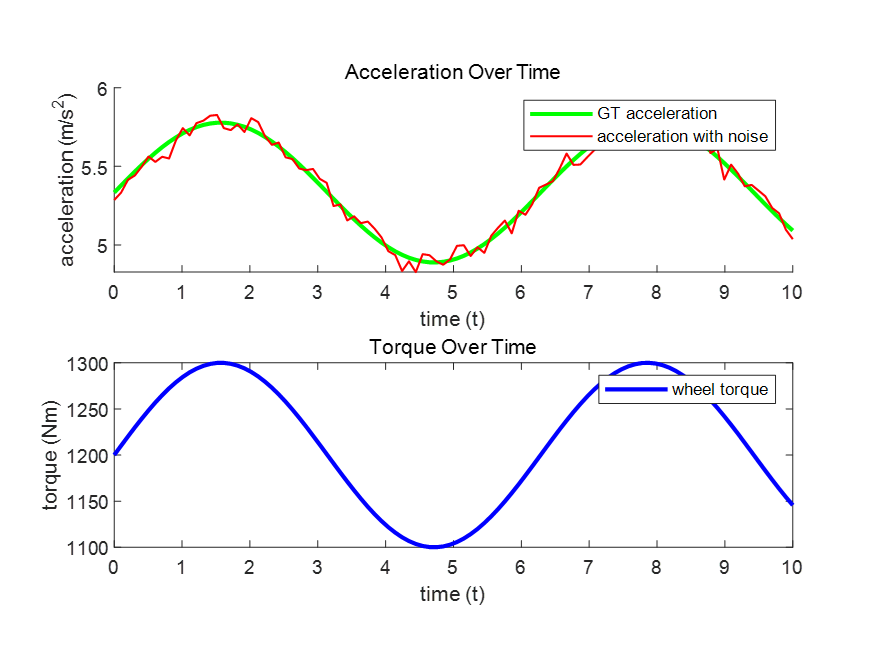

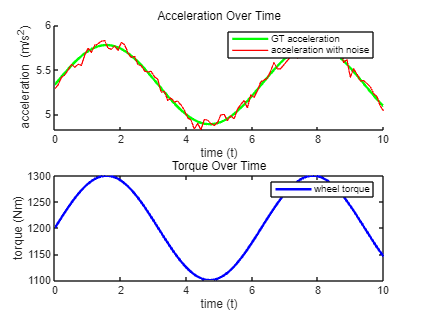

clear; close all;
load('least_square_mat_file_practice1.mat');
sim_total_steps = length(time);

figure;
subplot(2,1,1);
hold on;
plot(time, gt_accelerations_mps2, 'g-', 'LineWidth', 2);
plot(time, accelerations_with_noise_mps2, 'r-', 'LineWidth', 1);
xlabel('time (t)');
ylabel('acceleration (m/s^2)');
legend('GT acceleration', 'acceleration with noise');
title('Acceleration Over Time');

subplot(2,1,2);
plot(time, torques_Nm, 'b-', 'LineWidth', 2);
xlabel('time (t)');
ylabel('torque (Nm)');
legend('wheel torque');
title('Torque Over Time');
hold off;

### Least square modeling

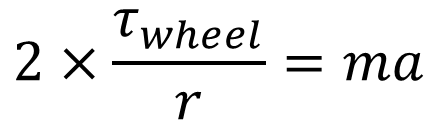

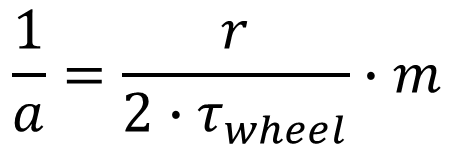

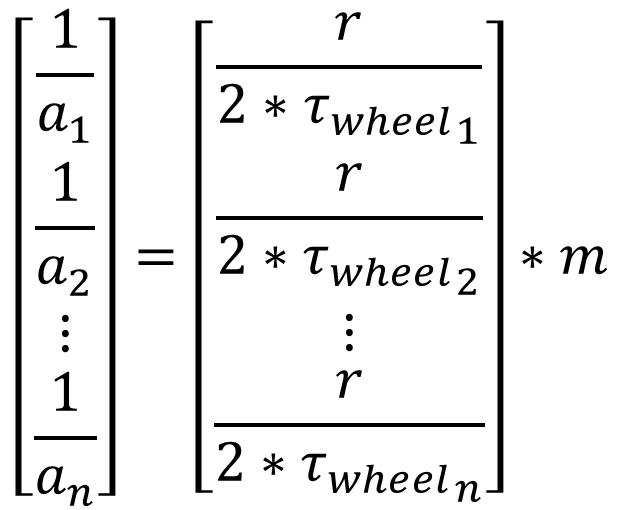

- y: measurement vector

- x: state vector

Num_of_state = 1; % mass_kg
Num_of_measurement_order = 1; % acceleration
H = zeros(sim_total_steps, Num_of_state);
Y = zeros(sim_total_steps, Num_of_measurement_order);

for idxSim = 1: sim_total_steps
    %%%% TODO %%%%
    H(idxSim, 1) = wheel_radius_m/(2*torques_Nm(idxSim)) ;
    Y(idxSim, 1) = 1/accelerations_with_noise_mps2(idxSim) ;
end

### Solving least sqaure

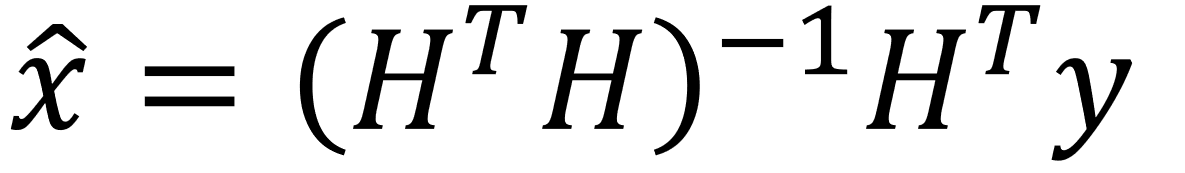

%%%% TODO %%%%
% estimated_mass = XXXXXX ;
estimated_mass = inv((H.')*H)*(H.')*Y;

% Estimated result
fprintf('Estimated mass: %.2f kg\n', estimated_mass);

Estimated mass: 1500.35 kg


fprintf('GT mass: %.2f kg\n', gt_mass_kg);

GT mass: 1500.00 kg


### Visualize Result

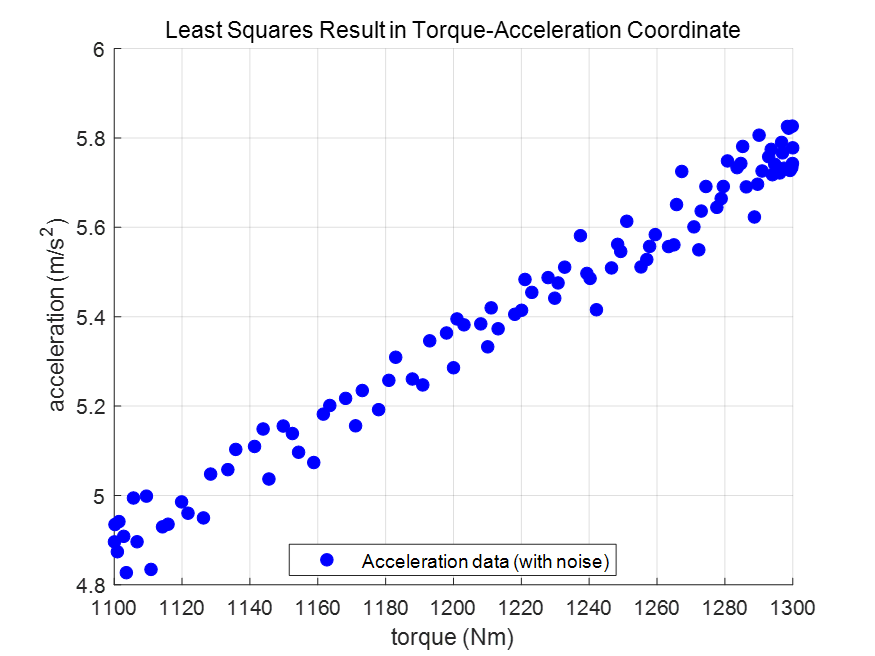

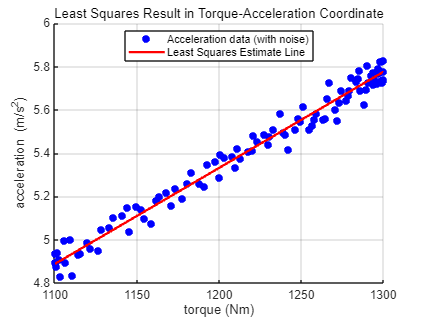

figure;
hold on;
plot(torques_Nm, accelerations_with_noise_mps2, 'bo', 'MarkerFaceColor', 'b');
torques_line = linspace(min(torques_Nm), max(torques_Nm), 100);
accelerations_line = (2 * torques_line / wheel_radius_m) / estimated_mass;
plot(torques_line, accelerations_line, 'r-', 'LineWidth', 2);
xlabel('torque (Nm)');
ylabel('acceleration (m/s^2)');
title('Least Squares Result in Torque-Acceleration Coordinate');
legend('Acceleration data (with noise)', 'Least Squares Estimate Line', 'Location', 'best');
grid on;
hold off;

## Practice 2: Estimate initial position, velocity, and acceleration

### Problem

There is a **free-falling object**.

The **range sensor** can measure the **altitude of a free-falling object**.

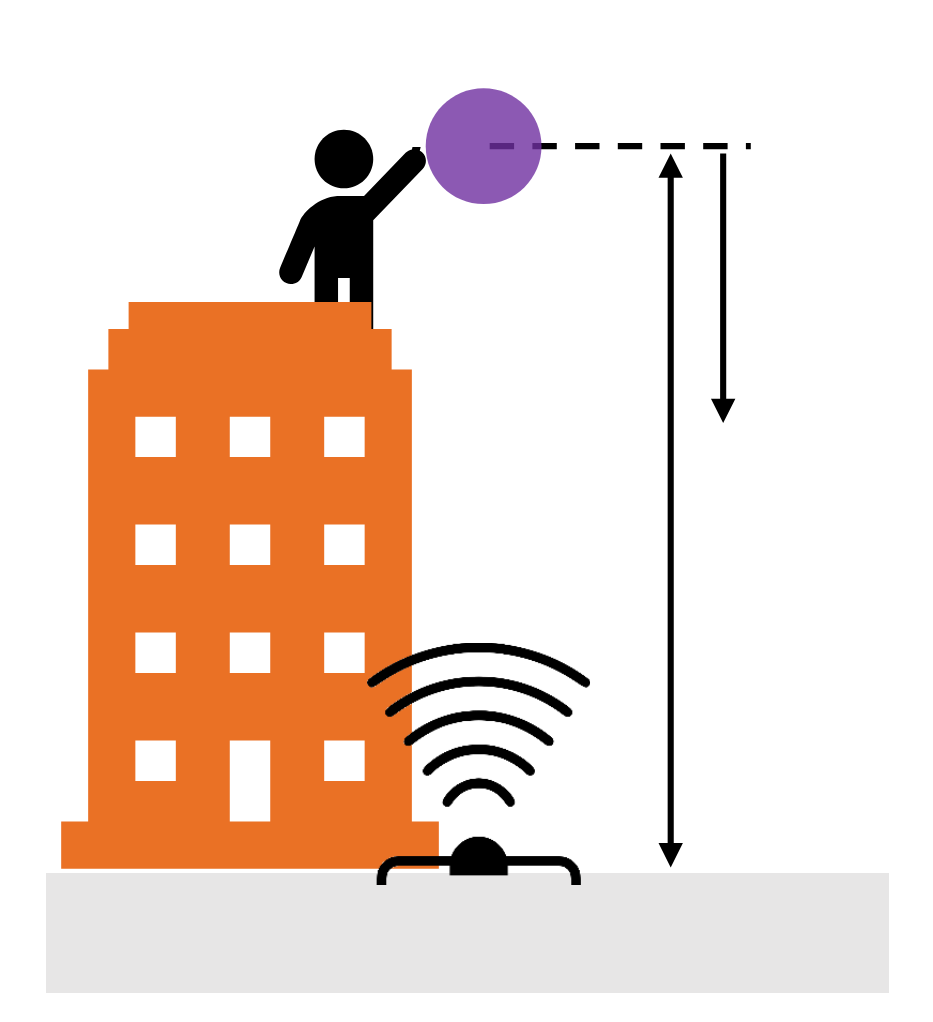

A discrete model of the free-falling object can be represented as follow: 

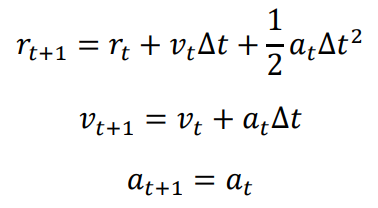

The discrete state space description of this system can be written as follow:

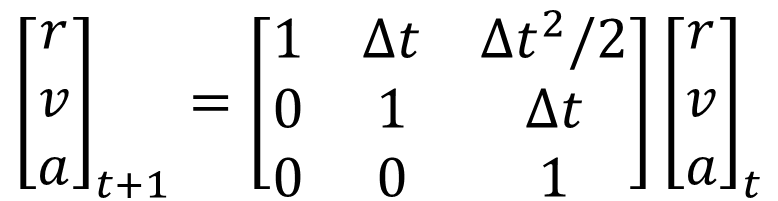

We have the sampling time and initial information as below:

1) ∆𝑡 = 0.1

2) gravitational acceleration (𝑎 = 𝑔 = −9.80665 𝑚/𝑠^2 ) model

3) initial velocity 𝑣_0 = 2.5 𝑚/𝑠

4) initial range 𝑟_0 = 100 𝑚

### Measurement data

Plot the simulation (x-axis is time and y-axes are r_t, v_t, and a_t.)

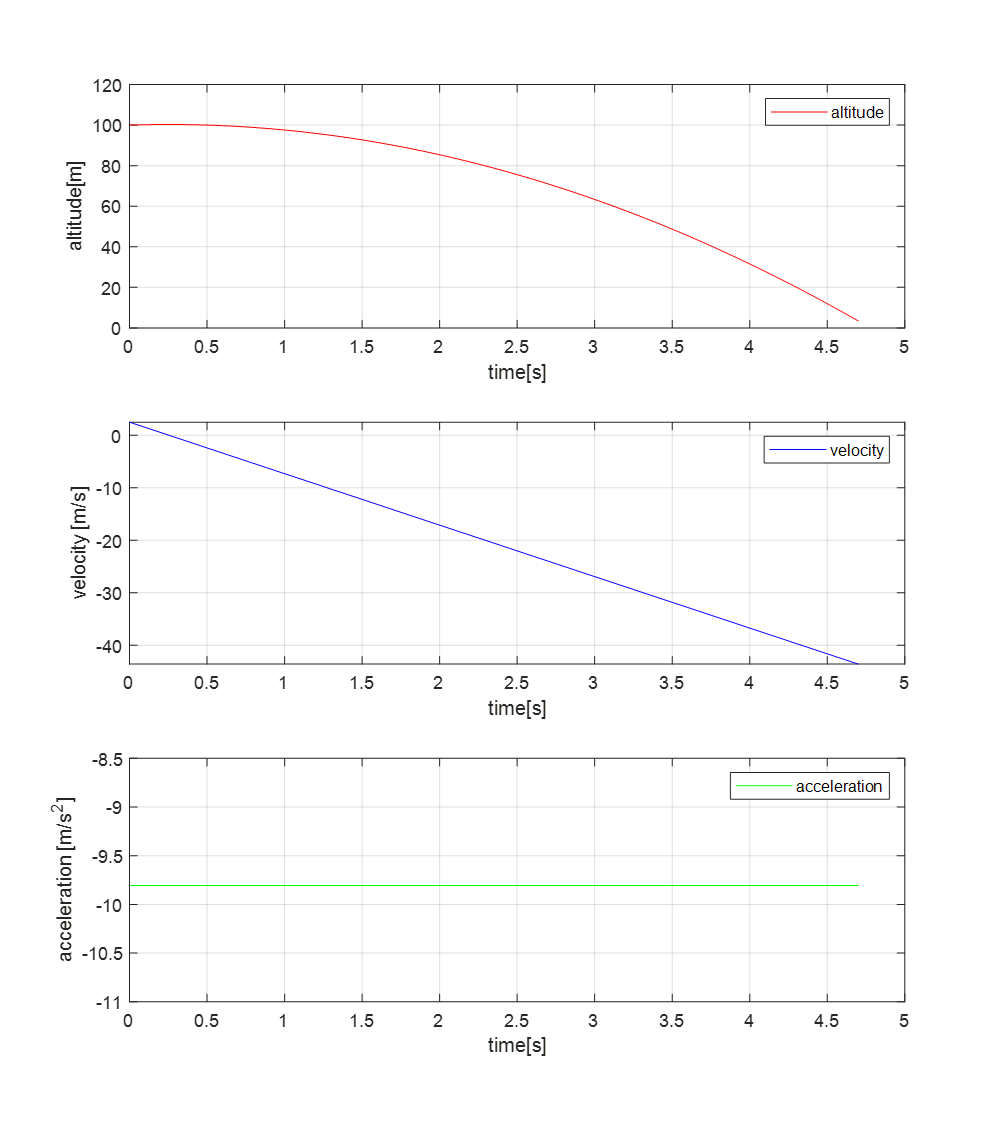

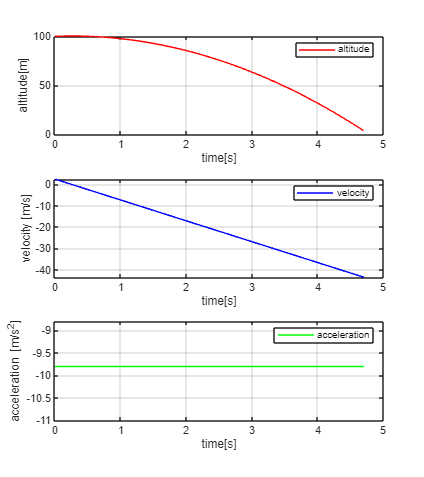

clear; close all;
load('least_square_mat_file_practice2.mat');

% Plot
figure('Name','Practice 2: Simulation data','Position',[100,100,840,945]);

hold on; 

subplot(3,1,1)
plot(sim_time, sim_altitude, 'r');
legend('altitude'); xlabel('time[s]'); ylabel('altitude[m]'); grid on;

subplot(3,1,2)
plot(sim_time, sim_velocity, 'b');
legend('velocity');
xlabel('time[s]'); ylabel('velocity [m/s]'); grid on;

subplot(3,1,3)
plot(sim_time, sim_acceleration, 'g');
legend('acceleration'); xlabel('time[s]'); ylabel('acceleration [m/s^2]'); grid on;

hold off

### Least square modeling

Find the r0, v0, and a0 using simulation data through least square estimation.

A discrete model of the free-falling object can be represented as follow: 

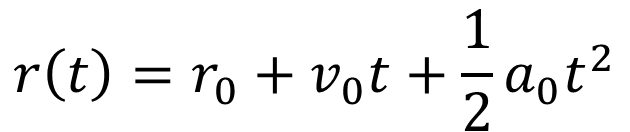

The discrete state space description of this system can be written as follow:

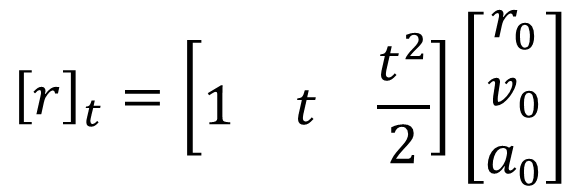

      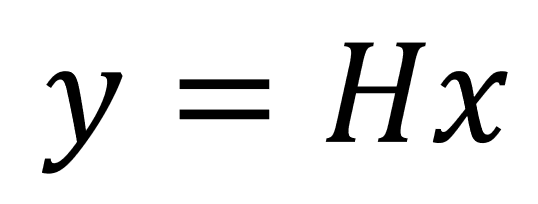

- y: Measurement vector

- x: State vector

num_of_state_order = 3; % r0, v0, a0
num_of_measurment_order = 1; % range
H = zeros(sim_total_steps, num_of_state_order);
Y = zeros(sim_total_steps, num_of_measurment_order);

for idxSim = 1: sim_total_steps
    %%%% TODO %%%%
    H(idxSim,:) = [1, sim_time(idxSim), sim_time(idxSim).^2/2] ;
    Y(idxSim,1) = sim_altitude_sensor(idxSim);
end

### Solving least sqaure

% Calculate estimated value
%%%% TODO %%%%
% estimated_x_ls = XXXXXX ;
estimated_x_ls = inv((H.')*H)*(H.')*Y ;

sim_true = [init_altitude; init_velocity; init_acceleration];
error_ls = abs(estimated_x_ls - sim_true);

% Estimated result
fprintf('Least Square result   \n');

Least Square result   


fprintf('Estimated r0: %f, v0: %f, a0: %f   \n', estimated_x_ls(1), estimated_x_ls(2), estimated_x_ls(3));

Estimated r0: 103.863489, v0: -1.149166, a0: -8.462156   


fprintf('GT r0: %f, v0: %f, a0: %f   \n', sim_true(1), sim_true(2), sim_true(3));

GT r0: 100.000000, v0: 2.500000, a0: -9.806650   


fprintf('r0_error: %f, v0_error: %f, a0_error: %f   \n', error_ls(1), error_ls(2), error_ls(3));

r0_error: 3.863489, v0_error: 3.649166, a0_error: 1.344494   


## Practice 3: Weighed Least Square

### Problem

There is a **free-falling object**.

The **range sensor** can measure the **altitude of a free-falling object **and the **noise distribution **of the range sensor **changes proportionally with the range**.

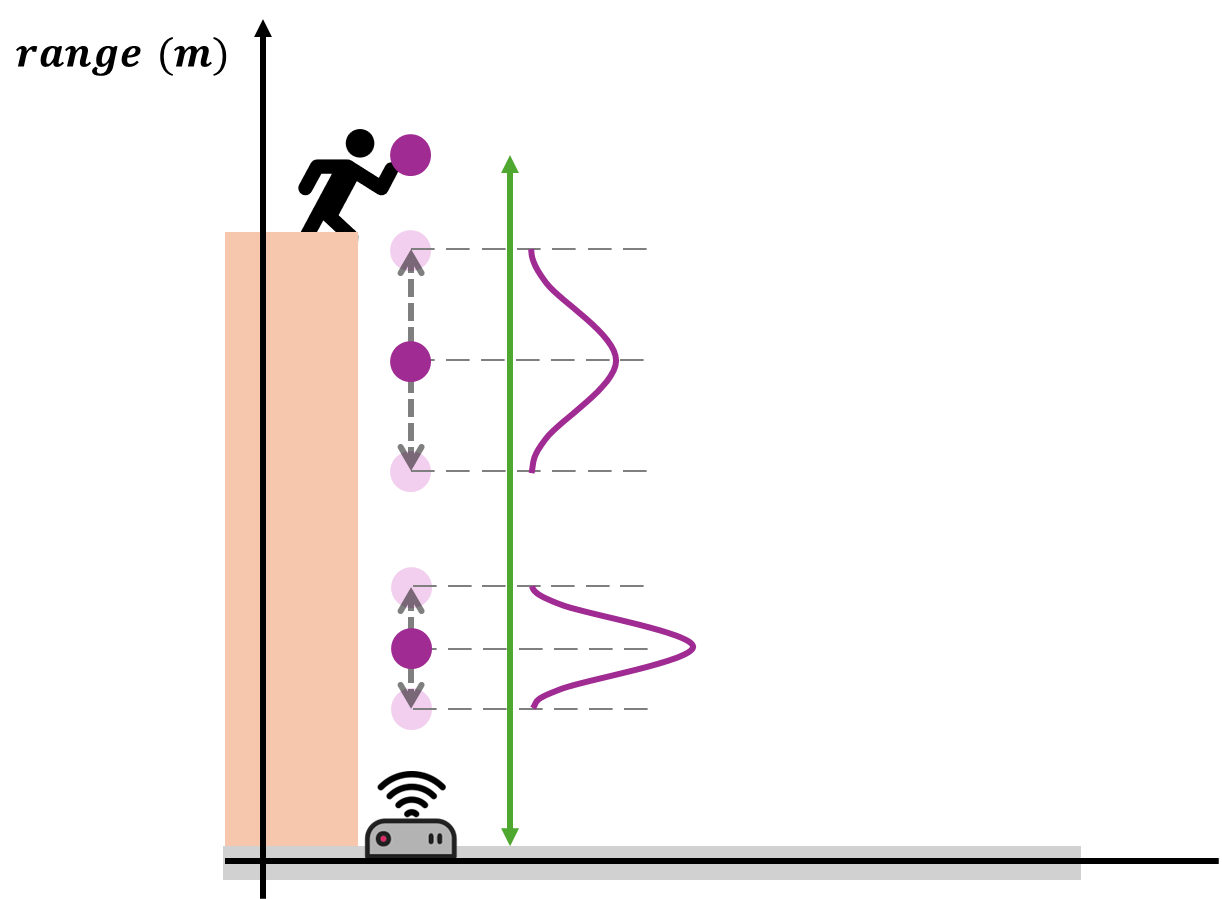

A range sensor model can be represented as follow: 

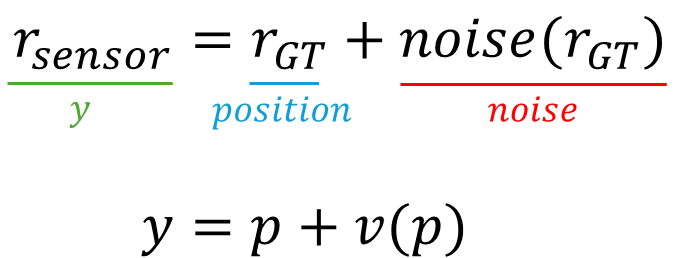

- y : **Position** of the target object **measured by a range sensor**

- p : **Actual Position** of the target object

- v : **Measurement Noise** at the position of the target object

The **noise distribution** of this sensor is normally distributed.

The '**Actual range [m]**' as the** mean (μ)** and 

'**Actual range * 0.1 [m]**' as the** standard deviation (σ)**.

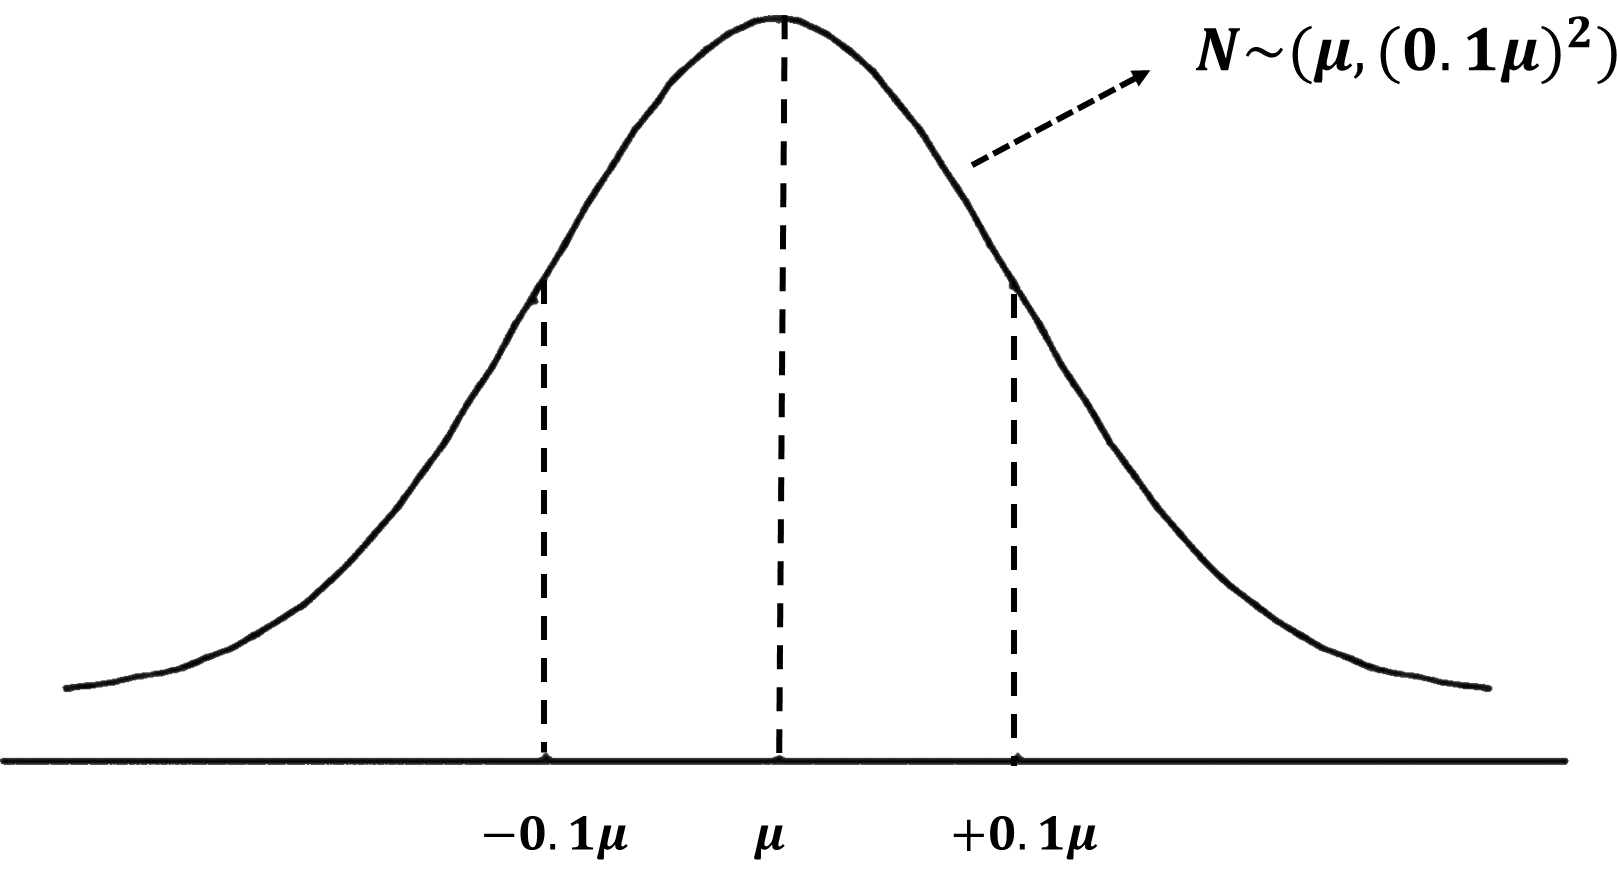

- μ : **Actual range** [m] -- **Mean** of the noise distribution

- σ : **Actual range * 0.1** [m] -- **Standard deviation** of the noise distribution

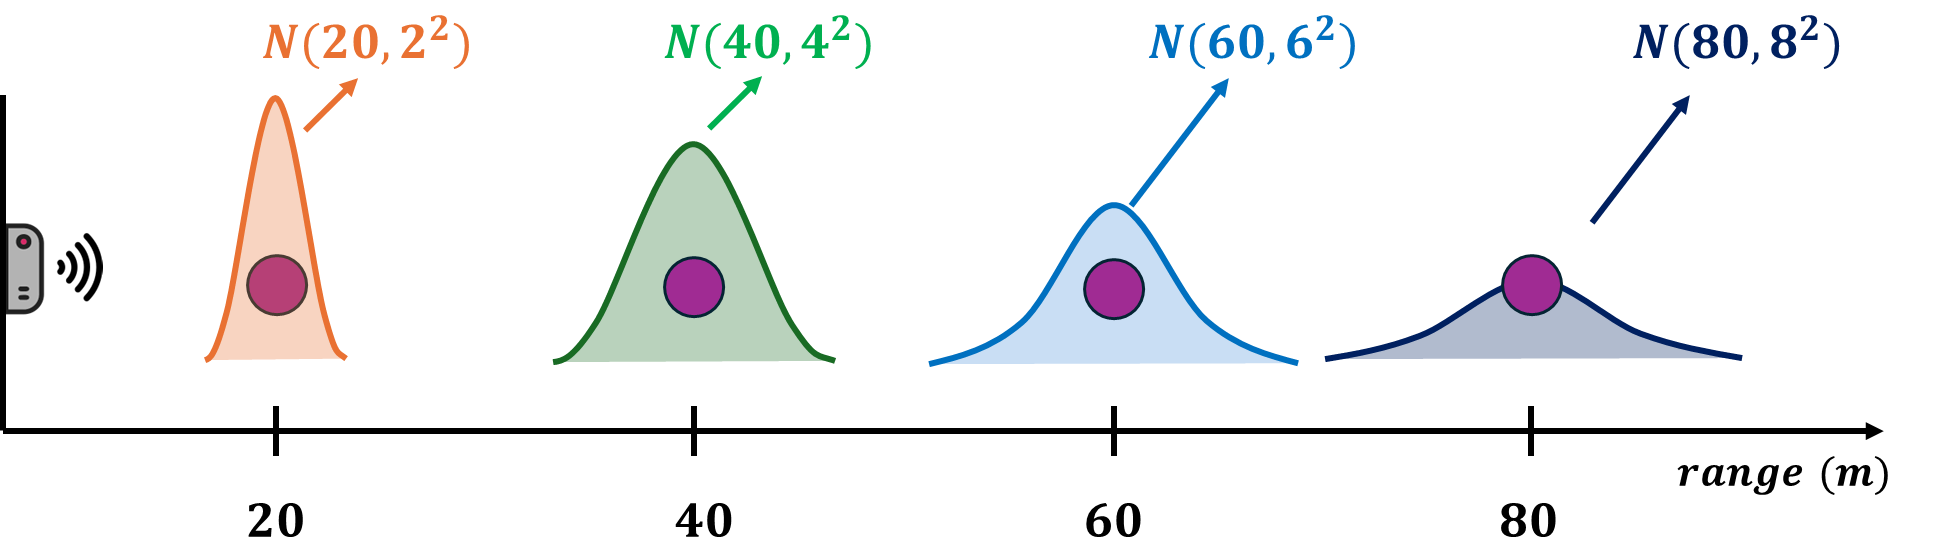

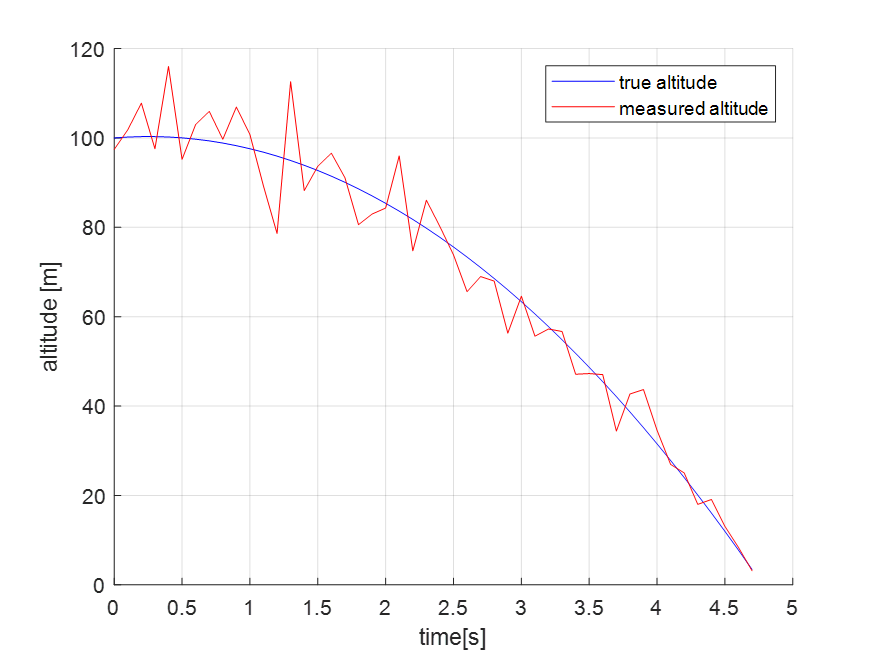

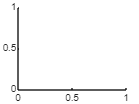

% Plot
figure('Name','Practice 2: Measurement data with noise');
hold on;

plot(sim_time, sim_altitude, 'b');

'sim_time'은(는) 인식할 수 없는 함수 또는 변수입니다.

plot(sim_time, sim_altitude_sensor, 'r');
legend('true altitude', 'measured altitude'); xlabel('time[s]'); ylabel('altitude [m]'); grid on;
title("Practice 2: Measurement data with noise")
hold off;

### Weighted Least Square

Find the r0, v0, and a0 using simulation data through weighted least square estimation.

The discrete state space description of this system can be written as follow:

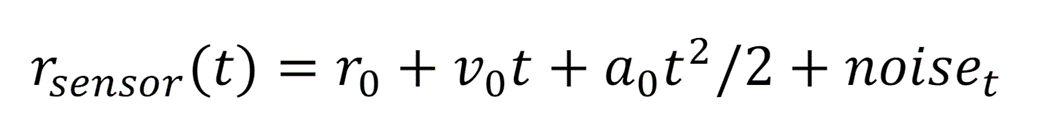

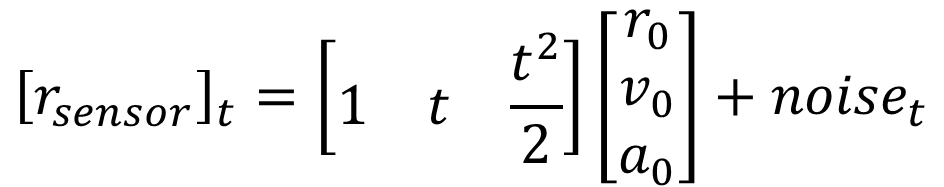

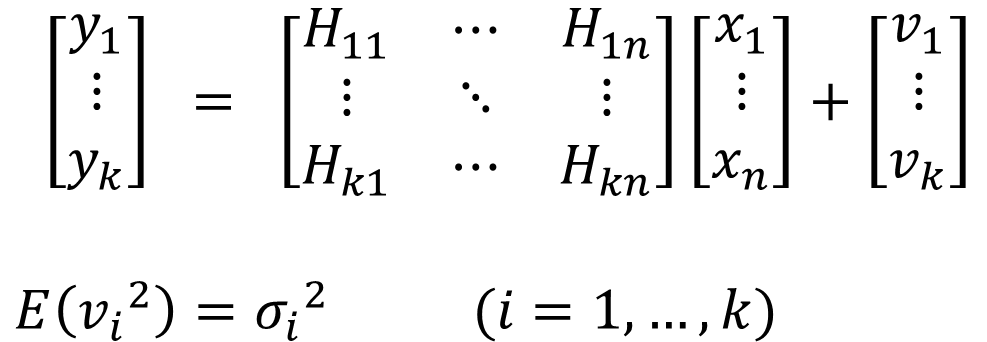

- y: Measurement vector

- x: State vector

- v: Measurement noise vector

- σ: Standard deviation of the noise distribution

### Measurement Covariance Modeling

Based on the noise distribution of the sensor mentioned above, construct the R matrix.

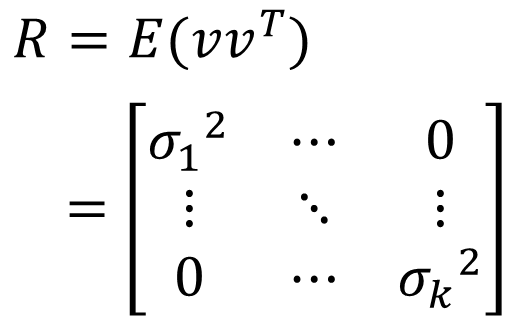

R = zeros(sim_total_steps, sim_total_steps);

for idxSim = 1: sim_total_steps
    %%%% TODO %%%%
    R(idxSim,idxSim) = (0.1* sim_altitude(idxSim))^2;
end


### Solving Weighted Least Square

%%%% TODO %%%%
% estimated_x_wls = XXXXXX ;
estimated_x_wls = inv(H.'*inv(R)*H)*(H.')*inv(R)*Y;

sim_true = [init_altitude; init_velocity; init_acceleration];
error_wls = abs(estimated_x_wls - sim_true);

% Estimated result
fprintf('\nGT r0: %f, v0: %f, a0: %f   \n', sim_true(1), sim_true(2), sim_true(3));


GT r0: 100.000000, v0: 2.500000, a0: -9.806650   



fprintf('\nWeighted Least Square result   \n');


Weighted Least Square result   


fprintf('Estimated r0: %f, v0: %f, a0: %f   \n', estimated_x_wls(1), estimated_x_wls(2), estimated_x_wls(3));

Estimated r0: 101.128943, v0: 2.266287, a0: -9.810207   


fprintf('r0_error: %f, v0_error: %f, a0_error: %f   \n', error_wls(1), error_wls(2), error_wls(3));

r0_error: 1.128943, v0_error: 0.233713, a0_error: 0.003557   



% Compare between Least Square & Weighted Least Square
fprintf('\nLeast Square result   \n');


Least Square result   


fprintf('Estimated r0: %f, v0: %f, a0: %f   \n', estimated_x_ls(1), estimated_x_ls(2), estimated_x_ls(3));

Estimated r0: 103.863489, v0: -1.149166, a0: -8.462156   


fprintf('r0_error: %f, v0_error: %f, a0_error: %f   \n', error_ls(1), error_ls(2), error_ls(3));

r0_error: 3.863489, v0_error: 3.649166, a0_error: 1.344494   
